# Multi-shell acquisitions and MAP-MRI (Work in Progress)

This demo illustrates the basic use of the MAP-MRI/MAPL module, aimed at the analysis of multi-shell data sets.

setup__DMRIMatlab_toolbox('useparallel',false); % Will be ingnored if you don't have a licensed copy of the parallel toolbox
clear;
close('all');
lambda = nan; % use GCV
tau = 36.5e-3;
ADC0 = 3.0e-3;
Nmax = 6; % Using larger Nmax will blow up computation times

## Load data

Load first your own sutiable multi-shell dMRI data set, which should include the attenuation signal (DWI over the averaged baseline), the mask to remove the background, the gradients table, and the b-values for each gradient direction:

tic;
load test_data.mat;
T=toc; % This is always a large piece of data
fprintf(1,'It took %f seconds to load data\n',T);

It took 0.700557 seconds to load data


whos -file test_data.mat; % Check the variables loaded, their kinds, and their sizes

  Name        Size                        Bytes  Class      Attributes

  atti      101x110x17x256            193402880  single               
  bi        256x1                          2048  double               
  gi        256x3                          6144  double               
  mask      101x110x17                   188870  logical              



## Use only a few slices to accelerate the demo

slc = [4,9,14];
atti = atti(:,:,slc,:);
mask = mask(:,:,slc);
slc = [1,2,3];

## Compute the MAP-MRI coefficients

The number of coefficients to fit is governed by the "Nmax" parameter. The most usual values are Nmax=4 (22 coefficients) and Nmax=6 (50 coefficients). These coefficients are fitted by solving a quadratic programming problem with a cost function that penalized both the residual of the fitting and the energy of the Laplacian of the signal (the trade-off between the two terms is governed by the parameter "lambda"). Besides, the resulting diffusion propagator is forced to have integral one (this translates in an equality constraint over the MAP-MRI coefficients) and to be non-negative in a pre-defined Cartesian grid whose density is controlled buy the parameter "constRad".

tic;
[mapl,dti,lopt] = atti2mapl( atti, gi, bi, 'mask', mask, ...
    'tl', 1.0e-7, 'tu', 1-1.0e-7, ... % To avoid outliers
    'Nmax', Nmax, ...
    'ADC0', ADC0, ...
    'lambda', lambda, ...
    'tau', tau, ...
    'const', true, ...
    'constRad', 5, ...  % ((2*5+1)^3+1)/2 = 666 constraints
    'maxthreads', 8 ...
    );
fprintf(1,'It took %1.3f seconds to estimate the MAP-MRI coefficients\n',toc); % This will be a good while!

It took 13.353 seconds to estimate the MAP-MRI coefficients


## Compute some standard measures

From the MAP-MRI coefficients, a number of popular diffusion scalar measurements can be computed, typically defined as integrals over the domain of the attenuation signal itself or its Fourier transform.

ng = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','g');
e0 = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','e');
rtop = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','o');
rtap = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','a');
rtpp = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','p');
msd = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','m');
qiv = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','q');
padti = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','d');
u0 = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','u');
leng = mapl2index(mapl,dti,'mask',mask,'tau',tau,'ADC0',ADC0,'type','l');

## Prepare the plots

mapType = 'gray'; % Changing the colormap will trigger the entire demo
switch(mapType)
    case 'high'
        MAP = psychedelia(512);
    case 'gray'
        MAP = gray(512); % B/W colormap
    case 'default'
        MAP = parula(512);
end

## Plot the results

This is what you might expect for a typical diffusion MRI volume.

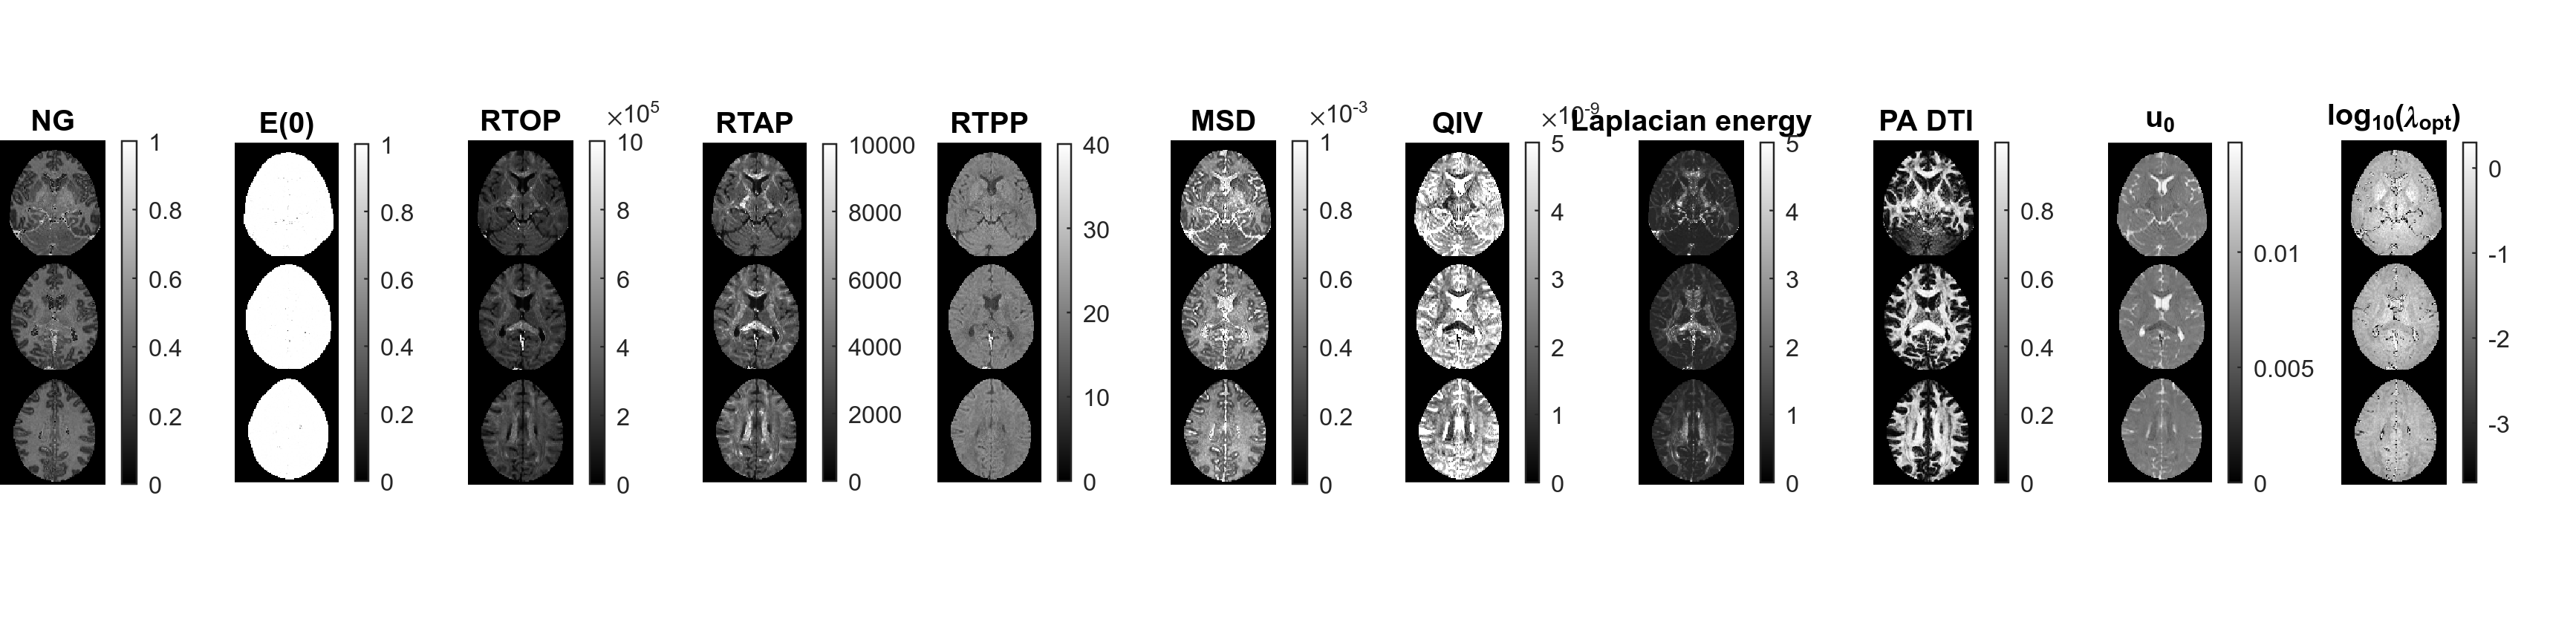

close(figure(1)); % Close previous figures if needed
hf = figure(1);
set(hf,'Name','MAPL indices from multi-shells','Position',[10,10,2800,680]);
R=1; C=11;
r=1; c=1; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([ng(:,:,slc(1))';ng(:,:,slc(2))';ng(:,:, ...
    slc(3))'],[0,1.0]); colormap(MAP); colorbar; title('NG');
axis('equal');axis('off');axis('tight');
r=1; c=2; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([e0(:,:,slc(1))';e0(:,:,slc(2))';e0(:,:, ...
    slc(3))'],[0,1.0]); colormap(MAP); colorbar; title('E(0)');
axis('equal');axis('off');axis('tight');
r=1; c=3; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([rtop(:,:,slc(1))';rtop(:,:,slc(2))';rtop(:,:, ...
    slc(3))'],[0.0,1.0e6]); colormap(MAP); colorbar; title('RTOP');
axis('equal');axis('off');axis('tight');
r=1; c=4; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([rtap(:,:,slc(1))';rtap(:,:,slc(2))';rtap(:,:, ...
    slc(3))'],[0.0,1.0e4]); colormap(MAP); colorbar; title('RTAP');
axis('equal');axis('off');axis('tight');
r=1; c=5; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([rtpp(:,:,slc(1))';rtpp(:,:,slc(2))';rtpp(:,:, ...
    slc(3))'],[0,40]); colormap(MAP); colorbar; title('RTPP');
axis('equal');axis('off');axis('tight');
r=1; c=6; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([msd(:,:,slc(1))';msd(:,:,slc(2))';msd(:,:, ...
    slc(3))'],[0,100e-5]); colormap(MAP); colorbar; title('MSD');
axis('equal');axis('off');axis('tight');
r=1; c=7; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([qiv(:,:,slc(1))';qiv(:,:,slc(2))';qiv(:,:, ...
    slc(3))'],[0,50e-10]); colormap(MAP); colorbar; title('QIV');
axis('equal');axis('off');axis('tight');
r=1; c=8; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([leng(:,:,slc(1))';leng(:,:,slc(2))';leng(:,:, ...
    slc(3))'],[0,5]); colormap(MAP); colorbar; title('Laplacian energy');
axis('equal');axis('off');axis('tight');
r=1; c=9; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([padti(:,:,slc(1))';padti(:,:,slc(2))';padti(:,:, ...
    slc(3))'],[]); colormap(MAP); colorbar; title('PA DTI');
axis('equal');axis('off');axis('tight');
r=1; c=10; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([u0(:,:,slc(1))';u0(:,:,slc(2))';u0(:,:, ...
    slc(3))'],[]); colormap(MAP); colorbar; title('u_0');
axis('equal');axis('off');axis('tight');
r=1; c=11; subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
loptl = log10(lopt).*mask;
imshow([loptl(:,:,slc(1))';loptl(:,:,slc(2))';loptl(:,:, ...
    slc(3))'],[log10(0.0002),log10(2)]); colormap(MAP); colorbar; title('log_{10}(\lambda_{opt})');
axis('equal');axis('off');axis('tight');

## DWI reconstruction (and comparison)

The MAP-MR coefficients can be used to recover the fitted attenuation signal at any desired gradients table.

tic;
atti2 = mapl2atti( mapl, dti, gi, bi, 'mask', mask );
fprintf(1,'It took %1.3f seconds to predict the attenuation signal\n',toc);

It took 0.067 seconds to predict the attenuation signal


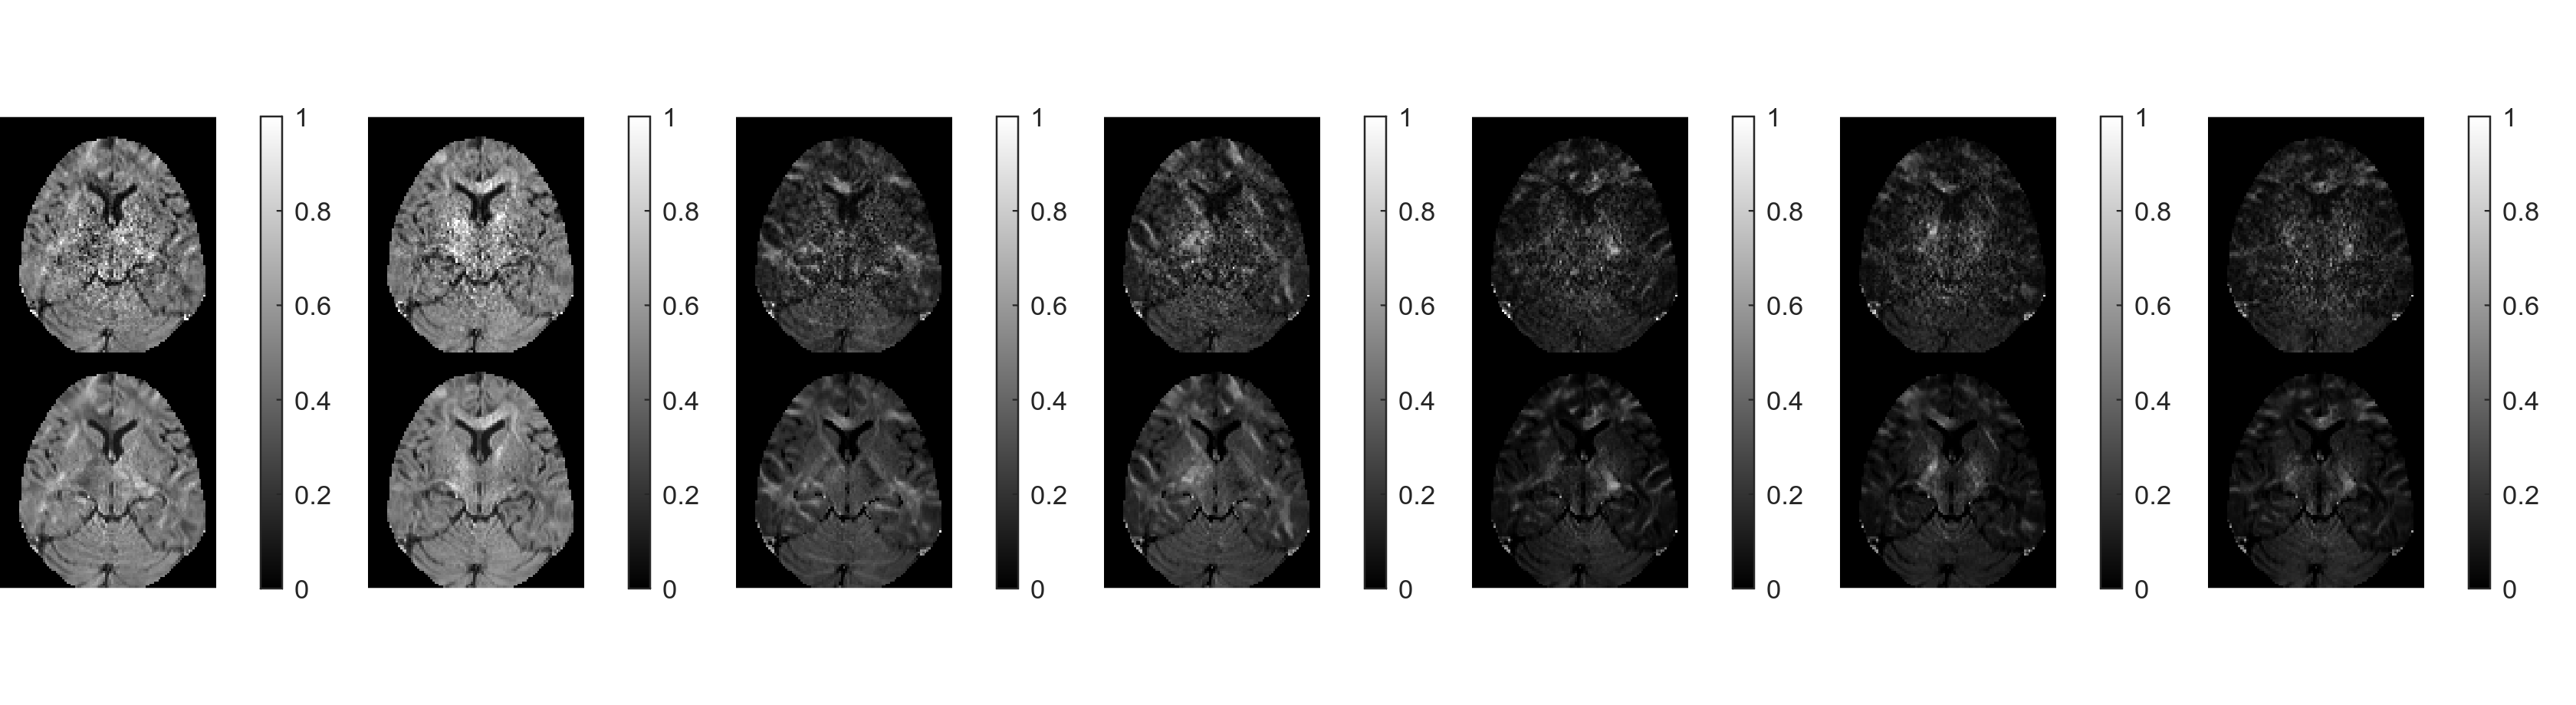

channels = [13,51,109,121,182,213,247];
close(figure(2)); % Close previous figures if needed
hf = figure(2);
set(hf,'Name','Original DWIs vs. reconstructed DWIs','Position',[10,10,1680,460]);
R=1; C=7;
% --
r=1; c=1; ch = channels(c);
subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([(double(mask(:,:,slc(1))).*atti(:,:,slc(1),ch))';atti2(:,:,slc(1),ch)'],[0,1.0]);
colormap(gray); colorbar;
axis('equal');axis('off');axis('tight');
% --
r=1; c=2; ch = channels(c);
subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([(double(mask(:,:,slc(1))).*atti(:,:,slc(1),ch))';atti2(:,:,slc(1),ch)'],[0,1.0]);
colormap(gray); colorbar;
axis('equal');axis('off');axis('tight');
% --
r=1; c=3; ch = channels(c);
subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([(double(mask(:,:,slc(1))).*atti(:,:,slc(1),ch))';atti2(:,:,slc(1),ch)'],[0,1.0]);
colormap(gray); colorbar;
axis('equal');axis('off');axis('tight');
% --
r=1; c=4; ch = channels(c);
subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([(double(mask(:,:,slc(1))).*atti(:,:,slc(1),ch))';atti2(:,:,slc(1),ch)'],[0,1.0]);
colormap(gray); colorbar;
axis('equal');axis('off');axis('tight');
% --
r=1; c=5; ch = channels(c);
subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([(double(mask(:,:,slc(1))).*atti(:,:,slc(1),ch))';atti2(:,:,slc(1),ch)'],[0,1.0]);
colormap(gray); colorbar;
axis('equal');axis('off');axis('tight');
% --
r=1; c=6; ch = channels(c);
subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([(double(mask(:,:,slc(1))).*atti(:,:,slc(1),ch))';atti2(:,:,slc(1),ch)'],[0,1.0]);
colormap(gray); colorbar;
axis('equal');axis('off');axis('tight');
% --
r=1; c=7; ch = channels(c);
subplot('Position',[(c-1)/C,(r-1)/R,1/C,1/R]);
imshow([(double(mask(:,:,slc(1))).*atti(:,:,slc(1),ch))';atti2(:,:,slc(1),ch)'],[0,1.0]);
colormap(gray); colorbar;
axis('equal');axis('off');axis('tight');

% --

## What remains to be done?

- Coputation of Orientation Distribution Functions (ODFs) from the MAP-MRI coefficients (near future)

- Computaton of the Ensemble Average Propagator (EAP) at desired points (near future)

- Computation of several other scalar indices:

-         Parallel and perpendicular NG (near future)

-         Propagator anisotropy